# MATLAB Functions

## Scope

- When writing and using functions, one must always be aware of **what information is visible to what function**

- Scope refers to the extent to which a variable is visible - can be referenced and/or altered

- *Local *– variable is only visible to the function in which it is defined

- *Global* – visible to all functions within a program

- *Persistent* – visible to all functions, but can only be altered by original function (rarely used)

## File Functions

- Called like any other *built-in *functions

- A Function is defined in one *.m* file

- File must be name *functname.m *to be callable in MATLAB

- There *can* be multiple* <inputs> *and multiple* <outputs>* 

help dice

  dice simulates rolling N s-sided di, iter times and returns the total of the
  roll(s), the roll distributions, and distribution graphs



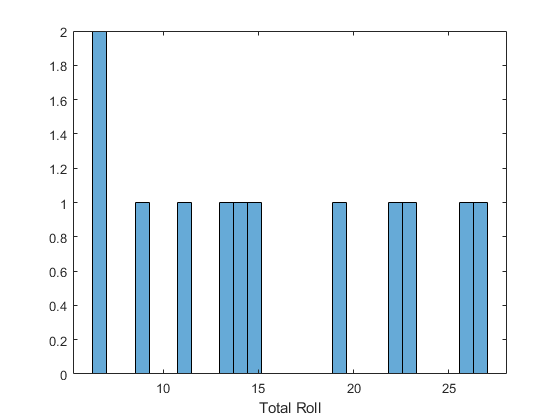

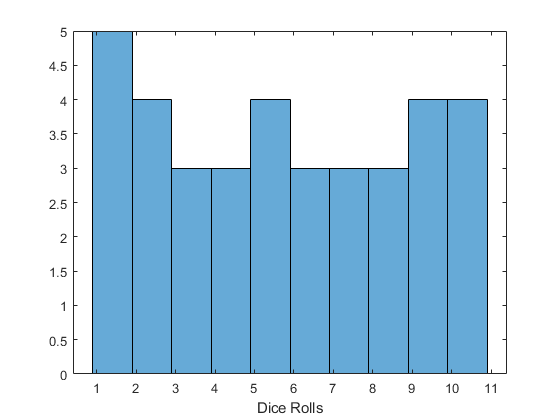

ans =     15
    23
     7
    13
    14
    27
     7
    19
    11
    26


dice(3,12,10)

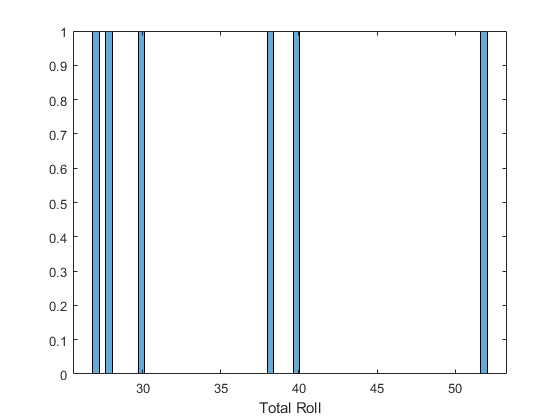

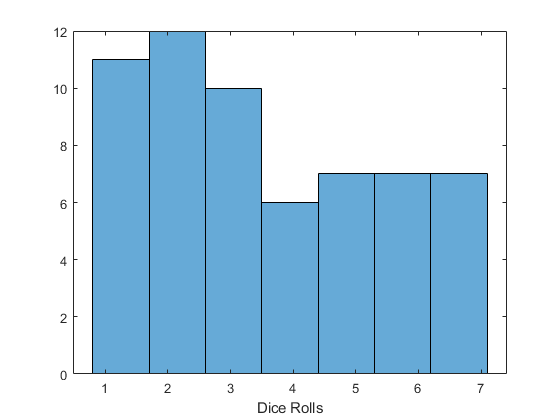

tot =     30
    27
    40
    28
    52
    38


dist =      2     4     3     3     3     2     5     1     4     3
     2     2     1     1     7     3     1     2     3     5
     2     6     2     7     3     1     2     5     6     6
     1     5     1     7     1     1     3     6     2     1
     7     3     2     4     6     7     6     5     5     7
     5     4     2     4     3     7     1     4     2     6


[tot,dist] = dice(10,6,7)

## Local Functions

MATLAB allows for multiple function definitions in a file 

the first function defined is the “main” function (callable from MATLAB command line)

Any other function defined after the “main” function is only visible to the functions in the same file AND cannot be called from the command line

Can call *help* on local functions by using a '*>' *character

*Note: Local functions take precedent over any externally defined function (you may “overload” function names using local functions)*

help dice>visual

  draws dice images based on rolls of DICE



## Nested Functions

**Nested functions are any functions defined inside a “parent” function**

Nested functions can access and change variables contained in the parent functions

 (this is a blessing and a curse)

type dice.m

## Anonymous Functions

- An anonymous function is **not** stored in a file, but associated with a *function handle*

- Can only contain a **single** executable statement

- Will become invaluable in ordinary differential equations

a = 1.3;
b = .2;
c = 30;
parabola = @(x) a*x.^2 + b*x + c;
y = parabola(1)

y =   31.500000000000000

a=10;
parabola(1)

ans =   31.500000000000000

parabola = @(a,b,c,x) a*x.^2 + b*x + c;
parabola(10,10,10,1)

ans =     30

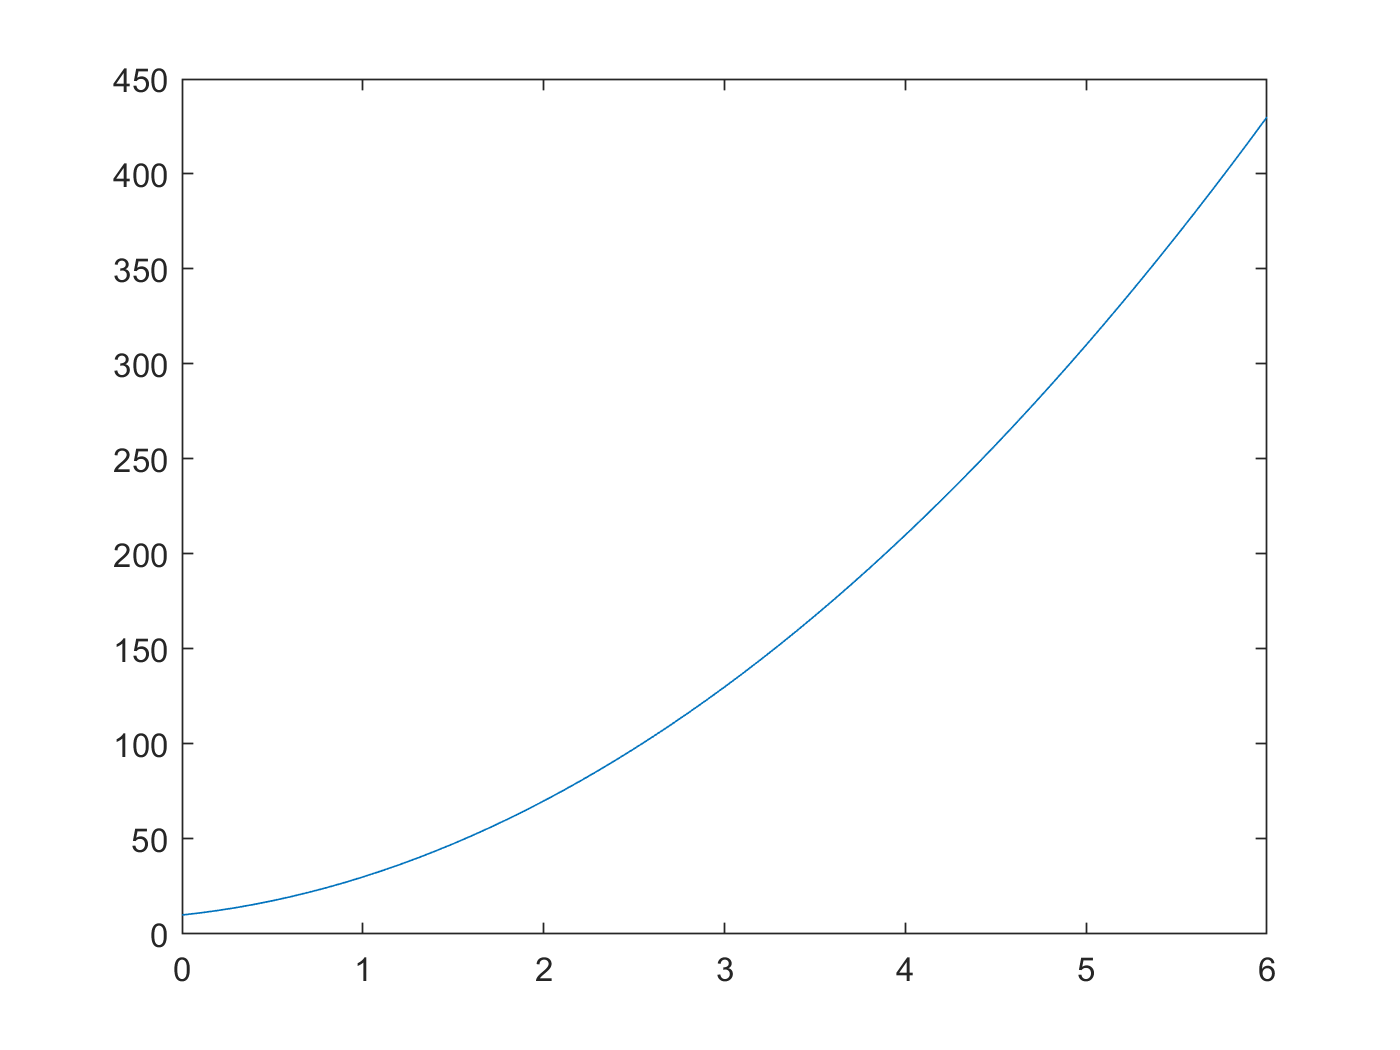

x=0:0.1:6;
plot(x,parabola(10,10,10,x))

## Order of Precedence

**When your functions have the same name as other functions/variables, MATLAB executes functions in this order**

1. Variables

2. Nested Functions within current function

3. Local Functions within current file

4.Private Functions/Object Functions/Class Constructors

5. Functions within current folder

6. Functions within other folders on MATLAB’s path